# **변경사항**

**2022.02.12**

- **  singlechannel, multichannel 각각 하나의 함수로 통합**

**2022.01.25**

- `readVerticalWithoutTime` 추가

# **1. readSingleChannel**

input

- `filename`: 파일 경로를 입력. xlsx, csv 파일 둘 다 가능.

- `timeColumnIdx`: 엑셀에서 데이터 파일을 열었을 때, 시간 변수가 적혀 있는 column의 위치. 예를 들어 C행에 적혀 있으면 3, F행에 적혀 있으면 6을 입력. **시간 변수가 없는 파일의 경우 0을 입력**

- `startRowIdx`: 엑셀에서 데이터 파일을 열었을 때, 관측치 데이터가 시작하는 row의 위치

- `startColIdx`: 엑셀에서 데이터 파일을 열었을 때, 관측치 데이터가 시작하는 column의 위치

- `sampleRate`: 시간 변수가 없는 파일의 경우 sampling frequency 값을 입력. 시간 변수가 있는 파일의 경우 nan을 입력

- `organoidNum, channelNum, month`: 관리를 위한 index, 데이터 처리에 영향을 미치지 않으므로 적절히 입력

## 예제 1. MEA data.xlsx

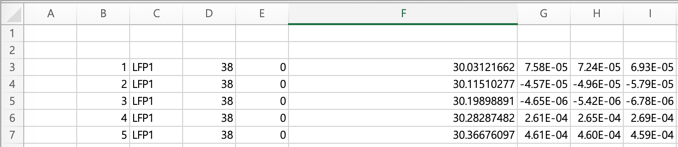

reader = channelReader();

                                    % filename,     timeColumnIdx  startRowIdx   startColIdx   sampleRate   organoidNum        channelNum     month
test_1 = reader.readSingleChannel("./data/MEA data.xlsx", 6,      3,             7,            nan,           1,              38,            1)

test_1 =   channel - 속성 있음:

              organoidNum: 1.0000e+000
               channelNum: 38.0000e+000
                    month: 1.0000e+000
                       sf: 3.0518e+003
                  msPerTs: 327.6800e-003
              nTimestamps: 61.1830e+003
                startTime: 30.0312e+000
            endTimeApprox: 50.0793e+000
           durationApprox: 20.0481e+000
                        t: [1×61183 double]
                      raw: [1×61183 double]
                 filtered: []
        timestampsPrePeak: []
       timestampsPostPeak: []
          spikeTimestamps: []
    spikeTimestampsMatrix: []
           spikeWaveforms: []
                  nSpikes: []
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: []
         meanSpikesStruct: []
             ISIbeforePCA: []
           

## 예제 2. Data 1.csv

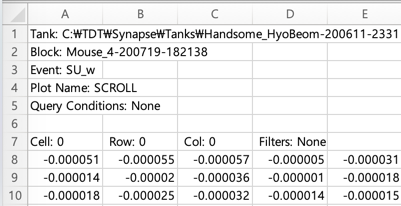

                                    % filename,     timeColumnIdx  startRowIdx  startColIdx    sampleRate     organoidNum   channelNum     month
test_2 = reader.readSingleChannel("./data/Data 1.csv",      0,       8,             1,            3152,           1,              1,         1);

파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.


ans =    -51.0000e-006   -55.0000e-006   -57.0000e-006    -5.0000e-006   -31.0000e-006   -32.0000e-006   -30.0000e-006    17.0000e-006    -8.0000e-006     7.0000e-006   -28.0000e-006   -27.0000e-006   -19.0000e-006   -12.0000e-006    -8.0000e-006   -13.0000e-006     5.0822e-021   -19.0000e-006   -20.0000e-006   -33.0000e-006    -5.0000e-006   -11.0000e-006   -17.0000e-006     1.0000e-006     3.0000e-006    46.0000e-006    92.0000e-006    97.0000e-006    86.0000e-006    94.0000e-006    77.0000e-006    56.0000e-006    48.0000e-006    52.0000e-006    47.0000e-006    62.0000e-006    70.0000e-006    63.0000e-006    44.0000e-006    45.0000e-006    33.0000e-006    15.0000e-006   -10.0000e-006   -14.0000e-006   -25.0000e-006   -16.0000e-006   -19.0000e-006   -26.0000e-006   -14.0000e-006   -50.0000e-006


## 예제 3. Data 2.csv

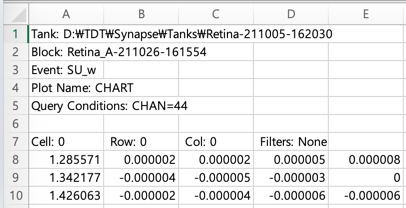

                                        % filename,    timeColumnIdx  startRowIdx   startColIdx   sampleRate     organoidNum   channelNum    month
test_3 = reader.readSingleChannel("./data/Data 2.csv",      1,            8,             2,            nan,           1,            1,        1);

파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.
1행의 관측치 수가 1382로, 2048개인 다른 행보다 관측치 수가 적습니다.


ans =      2.0000e-006     2.0000e-006     5.0001e-006     8.0001e-006     7.9999e-006     4.9998e-006     2.9999e-006   999.8442e-009   -13.8272e-012   -81.0601e-012    -1.0000e-006   118.1233e-012   -52.1717e-012    86.4814e-012     1.0002e-006     2.0001e-006     2.0000e-006     2.0000e-006     2.0000e-006     2.0002e-006     3.0000e-006     1.9996e-006   999.9525e-009   999.7612e-009    -1.0008e-006    -3.0003e-006    -2.9999e-006    -3.0000e-006    -3.0002e-006    -4.0003e-006    -3.9996e-006    -1.9991e-006   631.0659e-012     1.0002e-006   999.8066e-009  -751.7980e-012    -2.0008e-006    -3.0000e-006    -3.0004e-006    -3.9998e-006    -1.9987e-006   862.1409e-012   999.9382e-009  -652.8179e-012    -1.0006e-006    -2.0002e-006    -2.0003e-006    -3.0005e-006    -2.9996e-006    -1.9992e-006


## 예제 4. 추가 data.xlsx

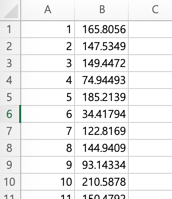

                                        % filename,     timeColumnIdx  startRowIdx   startColIdx   sampleRate     organoidNum   channelNum     month
test_4 = reader.readSingleChannel("./data/추가 data.xlsx",      0,       1,             2,            3152,           1,              1,          1);

ans =    165.8056e+000   147.5349e+000   149.4471e+000    74.9449e+000   185.2139e+000    34.4179e+000   122.8169e+000   144.9409e+000    93.1433e+000   210.5878e+000   150.4792e+000   388.9525e+000   213.2909e+000   206.0806e+000    30.4465e+000   158.9292e+000   115.8411e+000    88.7666e+000   102.4869e+000   191.1007e+000   376.1257e+000   584.6794e+000   870.2903e+000   740.9847e+000   638.1597e+000   353.6130e+000   252.2014e+000   500.5673e+000   316.7908e+000   386.1571e+000   292.7951e+000   249.3476e+000   198.3855e+000   109.7787e+000   324.9920e+000   184.0081e+000   146.9067e+000   175.1105e+000   115.8615e+000    78.2980e+000    93.4808e+000   118.5596e+000   108.6285e+000    86.8496e+000    83.1694e+000   114.2330e+000   157.2559e+000   135.6254e+000   104.5685e+000    74.5490e+000


# **2. readMultiChannelFile**

여러 채널 데이터가 포함된 파일 읽어오기

`readMultiChannelFile으로 파일 자체를 읽어옴`

- `filename`: 파일 경로를 입력. xlsx, csv 파일 둘 다 가능.

- `channelColumnIdx: `엑셀에서 데이터 파일을 열었을 때, channel 정보가 적혀 있는 column의 위치. 

- `timeColumnIdx`: 엑셀에서 데이터 파일을 열었을 때, 시간 변수가 적혀 있는 column의 위치. 예를 들어 C행에 적혀 있으면 3, F행에 적혀 있으면 6을 입력. **시간 변수가 없는 파일의 경우 0을 입력**

- `startRowIdx: `엑셀에서 데이터 파일을 열었을 때, 관측치 데이터가 시작하는 row의 위치

- `startColIdx: `엑셀에서 데이터 파일을 열었을 때, 관측치 데이터가 시작하는 column의 위치

- `sampleRate: `시간 변수가 없는 파일의 경우 sampling frequency 값을 입력. 시간 변수가 있는 파일의 경우 nan을 입력

`그 다음 아래의 두 가지 방법을 사용`

- `readSingleChannelFromFile: ``채널 번호를 특정하여 한 개의 채널의 데이터만 channel object로 만듦`

- `readManyChannelsFromFile: ``여러 채널 번호의 데이터를 channel object로 만듦. channel object의 리스트가 반환되며, {}로 인덱싱하면 개별 channel object가 나옴`

`1_singleunit wave.xlsx, 전체.xlsx `와 같은 포맷

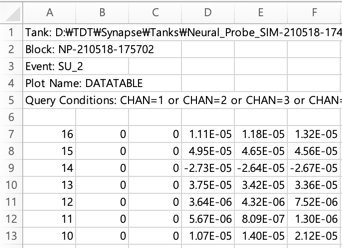     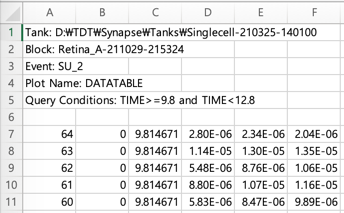

                - **7**번째 row부터 데이터 시작

                - channel number 기록되어 있음, chnnel이 여러 개 있음

                - row마다 시작 시간이 기록되어 있음

tic 
%                            filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("./data/전체.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴
toc % 코드 실행 시간 측정. 오래 걸림.

경과 시간은 51.358452초입니다.


% readSingleChannelFromFile: 원하는 channel 하나만 가져오기

%                                      organoid, channel, month 
test_5 = reader.readSingleChannelFromFile(1, 8, 1)

test_5 =   channel - 속성 있음:

              organoidNum: 1.0000e+000
               channelNum: 8.0000e+000
                    month: 1.0000e+000
                       sf: 24.4141e+003
                  msPerTs: 40.9600e-003
              nTimestamps: 73.7270e+003
                startTime: 9.8147e+000
            endTimeApprox: 12.8345e+000
           durationApprox: 3.0198e+000
                        t: [1×73727 double]
                      raw: [1×73727 double]
                 filtered: []
        timestampsPrePeak: []
       timestampsPostPeak: []
          spikeTimestamps: []
    spikeTimestampsMatrix: []
           spikeWaveforms: []
                  nSpikes: []
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: []
         meanSpikesStruct: []
             ISIbeforePCA: []
              

% readManyChannelsFromFile: 모든 channel 다 읽어와 배열로 만들기

%                                           organoid,  array of channel numbers, month 
pixels_test6 = reader.readManyChannelsFromFile(1,              1:64,                1 );

pixel1_test6_NEW = pixels_test6_NEW{1} % 64개 채널 중 첫 번째 채널을 선택

pixel1_test6_NEW =   channel - 속성 있음:

              organoidNum: 1.0000e+000
               channelNum: 1.0000e+000
                    month: 1.0000e+000
                       sf: 24.4141e+003
                  msPerTs: 40.9600e-003
              nTimestamps: 73.7270e+003
                startTime: 9.8147e+000
            endTimeApprox: 12.8345e+000
           durationApprox: 3.0198e+000
                        t: [1×73727 double]
                      raw: [1×73727 double]
                 filtered: []
        timestampsPrePeak: []
       timestampsPostPeak: []
          spikeTimestamps: []
    spikeTimestampsMatrix: []
           spikeWaveforms: []
                  nSpikes: []
                 PCScores: []
             explainedVar: []
                 clusters: []
                nClusters: []
        nSpikesPerCluster: []
     totalMeanSpikeStruct: []
         meanSpikesStruct: []
             ISIbeforePCA: []
    